Hankel变换

% f = @(u,v,rho) P(rho).*exp(i*u.*rho.^2/2).*besselj(0,rho.*v).*rho;
% P = @(rho) 1;
% N = 100;
% [U,V] = meshgrid(0:0.1:6,0:0.1:30);
% I = integral(@(rho) f(0,0:0.1:6,rho),0,1,'ArrayValued',1);
% plot(abs(I).^2)

普通积分

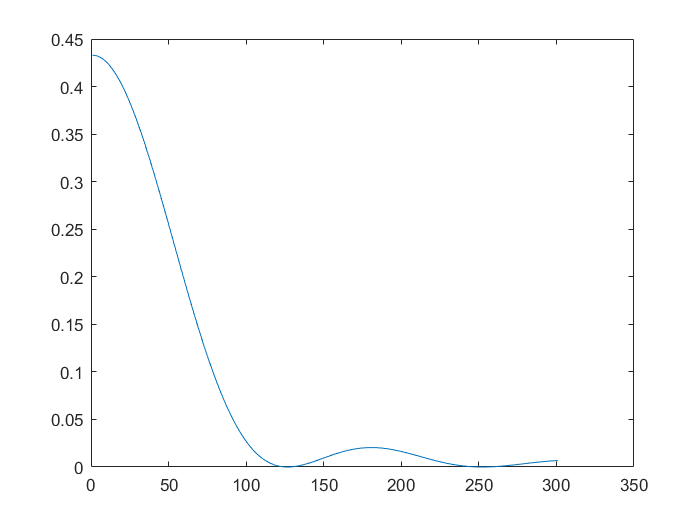

alpha = 70*pi/180;
P = @(theta) theta<= alpha;
F = @(theta,u,v) P(theta).*besselj(0,v.*sin(theta)/sin(alpha)).*exp(i*u*(sin(theta/2)).^2/(2*(sin(alpha/2)).^2)).*sin(theta);
[U,V] = meshgrid(0:0.1:6,0:0.1:30);
I = integral(@(theta) F(theta,V,U),0,alpha,'ArrayValued',1);
figure
plot(abs(I(:,1)).^2)